# Parametric modulation of epoch duration instead of amplitude

Often, we are analyzing fMRI activity in relation to processes that vary in  intensity or duration across events within a person, such as feeling intensity, the value assigned to an item, or decision time. 

Such processes are called "modulators".  

Analyzing fMRI activity in relation to within-person modulators can be a powerful way of linking brain and behavior across series of individual events, without influences of many of the variables that plague between-person correlations in individual differences.

When the **amplitude** of the neural response to a brief event can be assumed to scale with the modulator, we can use parametric modulation tools built into software packages like SPM and FSL. 

In many cases, however, we might like to allow the **duration** of neural activity to scale with the modulator, such as when analyzing individual differences in reaction time during cognitive tasks. in this case, we have to do some extra work to create variable-duration regressors and orthogonalize them with respect to the main regressors that capture the average response to each event type.  

The orthogonalization separates the responses linked to event-to-event variation in the modulator (the **modulator regressors**) from responses to events on average (the **standard regressors**).

SPM does this orthogonalization automatically in standard parametric modulation, which modulates event amplitude. This script shows you how to do this for duration-modulation, using CANlab Core Tools functions.  These can be entered as custom regressors in SPM or FSL if you wish. 

**Interpretation**

The example below shows variable-duration modulation with two event types. The interpretation of significant effects for "modulator regressors" shown below is that the duration of fMRI activity scales with the modulator value (see **caveats** below). Each modulator regressor tests the relationship between modulator values and activity for one event type.  

A [1 1] contrast in modulator regressors tests the relationship between modulator values and activity on average across both trial types. A [1 -1] contrast in modulator regressors across the two event types tests the interaction between event type and modulator values in predicting fMRI activity.

**References**

For a more in-depth discussion of how variable-duration events linked to reaction time (RT) in particular see the following papers. [Grinband et al. 2008](https://www.sciencedirect.com/science/article/pii/S1053811908009075) show that modeling RTs with variable-duration events can improve power in brain areas in which the RT influences the duration of activity.  Variable-duration events do not yield the same results as variable-intensity events, and it is important to consider this with respect to hypotheses underlying your particular tasks. [Mumford et al. 2024](https://www.nature.com/articles/s41562-023-01760-0) show that RT can confound effects otherwise attributable to differences across event types, creating artifacts in both within-person and between-person group analyses if not properly accounted for. They present expanded simulations and analyses of real datasets, extending the conversation about RT as a potential confound (cf. [Grinband et al. 2011](https://www.sciencedirect.com/science/article/pii/S1053811910016101)). 

Grinband, Jack, Judith Savitskaya, Tor D. Wager, Tobias Teichert, Vincent P. Ferrera, and Joy Hirsch. 2011. “The Dorsal Medial Frontal Cortex Is Sensitive to Time on Task, Not Response Conflict or Error Likelihood.” NeuroImage 57 (2): 303–11.

Grinband, Jack, Tor D. Wager, Martin Lindquist, Vincent P. Ferrera, and Joy Hirsch. 2008. “Detection of Time-Varying Signals in Event-Related fMRI Designs.” NeuroImage 43 (3): 509–20.

Mumford, Jeanette A., Patrick G. Bissett, Henry M. Jones, Sunjae Shim, Jaime Ali H. Rios, and Russell A. Poldrack. 2024. “The Response Time Paradox in Functional Magnetic Resonance Imaging Analyses.” Nature Human Behaviour 8 (2): 349–60.

**Caveats**

This tutorial only covers the technique of creating variable-duration modulators, and does not imply that this is appropriate in all situations. Mumford et al. 2024 cover scenarios in which orthogonalizing a modulator (RT) is not appropriate, because one is using a variable-duration regressor to control for RT when assessing event-type differences. Orthogonalization would render the RT regressor useless for that purpose.

We also do not mean to imply that any significant activity related to modulator regressors "proves" that duration-moduation is the right or best model. Other standard assumptions apply (e.g., choice of hemodynamic response function, linearity, etc.) and inferences are only as good as these assumptions, as usual.

## Generate simulated onsets and durations

SPM batch mode uses this style of cell array, with one column per condition (event type), and separate cell arrays for onsets and durations

onsets_in_sec = {[10 25 35 55]' [0 15 29 43]'};  % onsets for 2 conditions
durations = {[3 5 3.2 5.3]' [4 3 5.5 4.5]'};  % variable durations for each event

TR = 2; % TR in sec

meanduration = {};
onsets_with_durs = {};

## Use CANlab Core tools to build standard and modulator regressors

### Model with fixed durations

Here we are using the mean duration for all the events of each type as the single fixed duration

% Create fixed mean duration for each trial type
for i = 1:length(durations), meanduration{i} = repmat(mean(durations{i}), size(durations{i}, 1), 1); end 

% add durations as a column next to each set of onsets, for onsets2fmridesign compatibility
% Now each event type is still in a cell, but the cell has 2 columns, the 1st with onsets 
% and the 2nd with durations

for i = 1:length(onsets_in_sec), onsets_in_sec{i} = [onsets_in_sec{i}(:, 1) meanduration{i}(:, 1)]; end

Xavg = onsets2fmridesign(onsets_in_sec, TR, 80, 'hrf');

create_figure('Design matrices', 3, 1);
plotDesign(onsets_in_sec, [], TR, 'samefig');
title('Fixed single duration');
set(gca, 'XLim', [0 80]);

### Model with variable durations

% add durations as a column next to each set of onsets, for onsets2fmridesign compatibility
% Now each event type is still in a cell, but the cell has 2 columns, the 1st with onsets 
% and the 2nd with durations

for i = 1:length(onsets_in_sec), onsets_with_durs{i} = [onsets_in_sec{i}(:, 1) durations{i}(:, 1)]; end

Xdur = onsets2fmridesign(onsets_with_durs, TR, 80, 'hrf');

subplot(3, 1, 2);
plotDesign(onsets_with_durs, [], 2, 'samefig');
title('Variable duration');
set(gca, 'XLim', [0 80]);

% alternate plot of regressors
% figure; plot_matrix_cols(Xdur);

### Orthogonalize duration regressor to mean-duration regressor

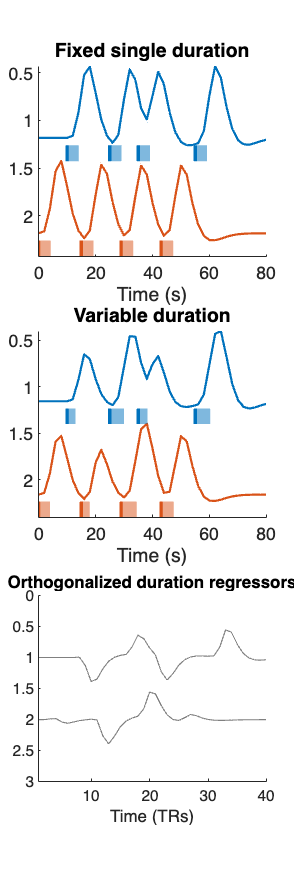

Xorth = [];

for i = 1:length(onsets_in_sec)

     Xorth(:, i) = resid(Xavg(:, i), Xdur(:, i), true); 

end

subplot(3, 1, 3);
plot_matrix_cols(Xorth);
title('Orthogonalized duration regressors')
xlabel('Time (TRs)')
set(gca, 'XLim', [1 40]);

### Construct full design matrix

with mean-duration regressors and orthogonalized duration regressors

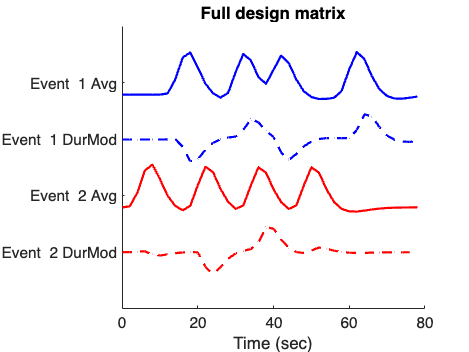

Xfull = [];
xnames = {};

for i = 1:length(onsets_in_sec)

     Xfull = [Xfull Xavg(:, i) Xorth(:, i)]; 

     xnames = [xnames {sprintf('Event%3.0f Avg', i)} {sprintf('Event%3.0f DurMod', i)}];
end

create_figure('Full design matrix');
linehan = plot_matrix_cols(Xfull, 'horiz', [0:TR:80-TR], {'b' 'b' 'r' 'r'});
set(linehan, 'LineWidth', 2);
set(linehan([2 4]), 'LineStyle', '--');
title('Full design matrix')

set(gca, 'YLim', [0 2*length(onsets_in_sec)+1], 'YTick', [1:2*length(onsets_in_sec)], 'YTickLabel', xnames)
xlabel('Time (sec)')
set(gca, 'XLim', [0 80])

**Interpretation redux**

We have shown variable-duration modulation with two event types. The interpretation of significant effects for "modulator regressors" (dashed lines) is that the duration of fMRI activity scales with the modulator value (see **caveats** above). Each modulator regressor tests the relationship between modulator values and activity for one event type.  

A [1 1] (or [0.5 0.5]) contrast in modulator regressors tests the relationship between modulator values and activity on average across both trial types. A [1 -1] contrast in modulator regressors across the two event types tests the interaction between event type and modulator values in predicting fMRI activity, i.e., whether the slope of the modulator-brain relationship varies across trials types.

There are other ways to parameterize this type of design, e.g., with a single regressor capturing modulator-related activity across all types and a second regressor capturing the interaction. As with all models, there is quite a bit of flexibilty and it's helpful to construct models that most directly and transparently address your specific hypotheses.

## Using an SPM.mat file to get onsets and durations

The onsets and modulator values for each event are stored in SPM already, assuming that you have set up a design with parametric modulation.

**SPM.Sess** is a structure in the SPM variable stored in the **SPM.mat** file. it contains all the onsets and modulator values you have entered in.

The example here assumes that you have entered both time and parametric modulation, so that parametric modulation is the 2nd modulator (**SPM.Sess.U(*).P(2).P**).  If you have not used the time modulator, modulator values will be in the first modulator structure: **SPM.Sess.U(*).P(1).P**

We also assume you have entered things in units of seconds, which onsets2fmridesign requires.

First load **SPM.mat**.  

Then:

Repeat for other event types in your design, or write a script to loop through them.

Then the code above should work for your design.